# Rayleigh distribution

## Generate probability density function (pdf) and cumulative distribution function (cdf)

The probabality density function of Rayleigh is,with the sigma as the scale parameter:


$$f\left(x,\sigma \right)=\frac{x}{\sigma^2 }e^{-x^2 /\left(2\sigma^2 \right)}$$
   

he cumulative distribution function of Rayleigh is:


$$F\left(x,\sigma \right)=1-e^{-x^2 /\left(2\sigma^2 \right)}$$


clear all;

scale_parameter =1; % scale parameter 
resolution_x = 0.01; % resolution on x axis

x= [0:resolution_x:10]; 
pdf_rayleigh = (x/scale_parameter^2).*exp(-x.^2/(2*scale_parameter^2)); % theory equation pdf
cdf_rayleigh = 1-exp(-x.^2/(2*scale_parameter^2));  % theory equation of cdf

## Manual integration of pdf shows the same profile as cdf

for c= 1:length(pdf_rayleigh)
    int_pdf_rayleigh(c) = sum(pdf_rayleigh([1:c]))*resolution_x;  % the area under the pdf curve is the integration operation
end    

## Plotting

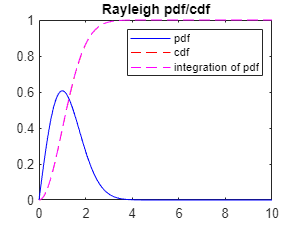

plot(x, pdf_rayleigh, '-b')
hold on;
plot(x, cdf_rayleigh, '--r')
hold on;
plot(x, int_pdf_rayleigh, '--m')
hold off;
legend('pdf', 'cdf','integration of pdf');
title('Rayleigh pdf/cdf');

## Expected value (mean value) calculation


$$\mathrm{Expected}\;\mathrm{value}\;\left(E\right)=\int_0^{\infty } \;x*\mathrm{pdf}\left(x\right)\mathrm{dx}$$


Should be: $\sigma \sqrt{\frac{\pi }{2}}\approx 1\ldotp 253\sigma$

expected_value = sum(pdf_rayleigh.*x)*resolution_x;
disp(sprintf('Expected value is %.5g, in the unit of sigma',expected_value/scale_parameter))

Expected value is 1.2533, in the unit of sigma


## standard deviation calculation

standard deviation = $\sqrt{\int_0^{\infty } \;{\left(x-E\right)}^2 *\mathrm{pdf}\left(x\right)\mathrm{dx}}$

Should be: $\sqrt{\left(2-\frac{\pi }{2}\right)}\sigma \approx 0\ldotp 655\sigma$

standard_deviation= sqrt(sum(pdf_rayleigh.*(x-expected_value).^2)*resolution_x);
disp(sprintf('Starndard deviation is %.5g, in the unit of sigma',standard_deviation/scale_parameter))

Starndard deviation is 0.65513, in the unit of sigma
